%Board Size
%Note board size is one less than you pick
columns = 14;
rows = 14;

limitC = columns - 1;
limitR = rows - 1;

%Treasure location
treasureX = randi([1 limitC]);
treasureY = randi([1 limitR]); 

%Creates the blank map
map = zeros(rows, columns);
map(map == 0) = NaN;

%Creates the colored in Map
[x2,y2] = meshgrid(1:columns,1:rows);
taxiMatrix = abs(treasureY - y2(:))+ abs(treasureX - x2(:));
finalMap = reshape(taxiMatrix,rows,columns);

%Treasure is very high values to it shows up correctly
finalMap(treasureY,treasureX) = 500;

%The colormap for the board with different colors to simulate an island
cmap = [0.6706 0.4588 0.0392; 0.4667 0.6745 0.1882; 0 1 0;1 0.9059 0.5216;0.0588 1 1; 0 0 1; 0 0.4471 0.7412;0.0314 0 0.4706; 1 1 0];

%Number of guesses the player made
guessNum = 0;


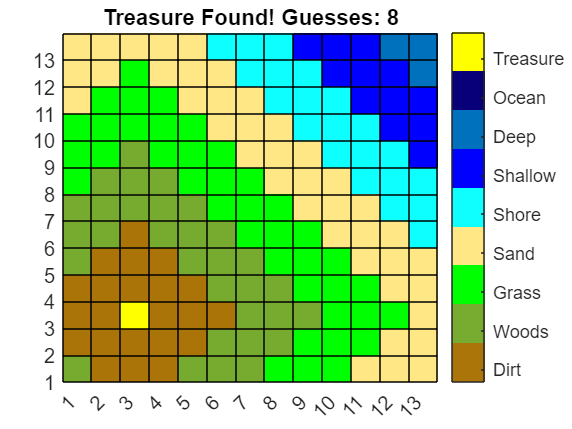

%Board Setup
p = pcolor(map);
hold on
xticks(1:1:limitC);
yticks(1:1:limitR);

colormap(cmap);
clim([0 rows*2]);

c = colorbar;
c.Ticks = 1:rows*2/9:rows*2;
c.TickLabels = {'Dirt','Woods','Grass','Sand','Shore','Shallow','Deep','Ocean', 'Treasure'};

title("Find the Treasure!")

%Play Game
 

if(guessNum ~= 0)
    guessX = 3;
    guessY = 3;

    %Run function to check guesses
    playGame(treasureX,treasureY,map,finalMap,guessX,guessY,guessNum)
    guessNum = guessNum + 1;
else
    %Increments the Guess Numbers to start the game
    guessNum = guessNum + 1;
end

function playGame(tX,tY,m,fm,gX,gY,gN)
    
    %If the guess is equal to the treasure location
    if(gX == tX)&&(gY == tY)
        %Fill in the whole grid
        pcolor(fm);
        %Display the new title
        finish = "Treasure Found! Guesses: " + gN;
        title(finish);
    %If the guess is not equal to the treasure
    else
        %Fill in the color of the location the guessed
        m(gY,gX) = fm(gY,gX);
        pcolor(m);
        
        %Display hint and guess number
        help = "You are " + string(fm(gY,gX)) + " away from the treasure.";
        guess = "Guess: " + gN;
        disp(help);
        disp(guess);
        disp("Guess again!");
        
    end
end